# Detect Lines in Images Using Hough

This example shows how to detect lines in an image using the H`ough` transform.

Read an image into the workspace and, to make this example more illustrative, rotate the image. Display the image.

clc;close all;clear all;

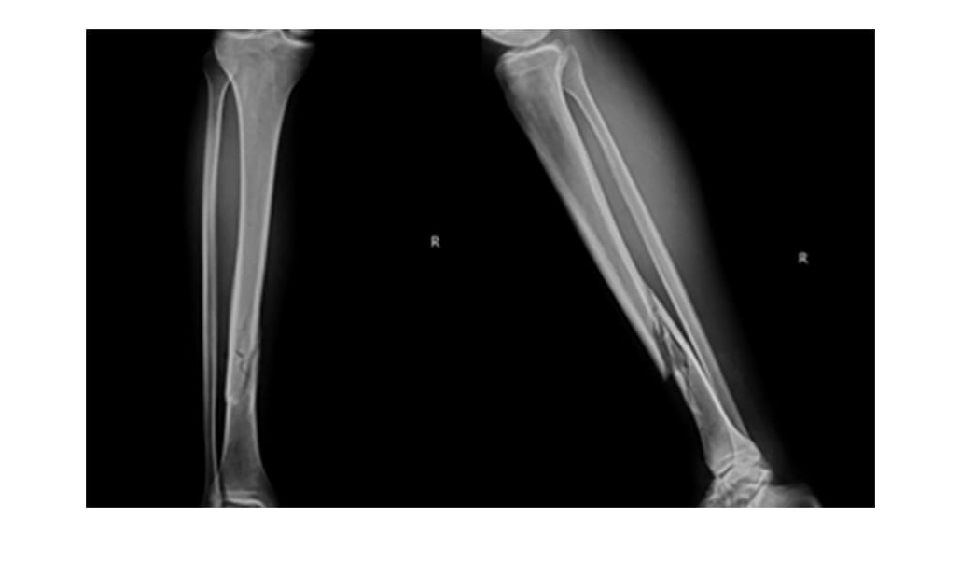

I = rgb2gray(imread('img1.jpeg'));
imshow(I)

Find the edges in the image using the `edge` function. 

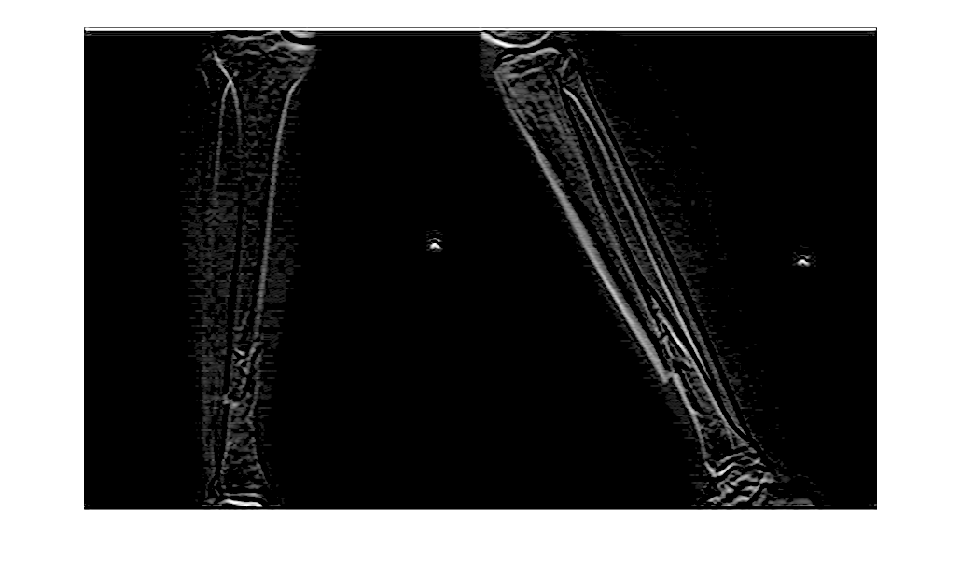

clf;
% BW = edge(I,'canny');
lap = fspecial('sobel');
BW = imfilter(I,lap,"replicate");
BW = imadjust(BW,[0 1],[0 1],0.5);
% % Bw = imbinarize(BW,"global");
imshow(BW);

Compute the Hough transform of the binary image returned by `edge`.

[H,theta,rho] = hough(BW);

Find the peaks in the Hough transform matrix, `H`, using the `houghpeaks` function.

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));

Find lines in the image using the `houghlines` function. 

lines = houghlines(BW,theta,rho,P,'FillGap',10,'MinLength',10);

Create a plot that displays the original image with the lines superimposed on it.

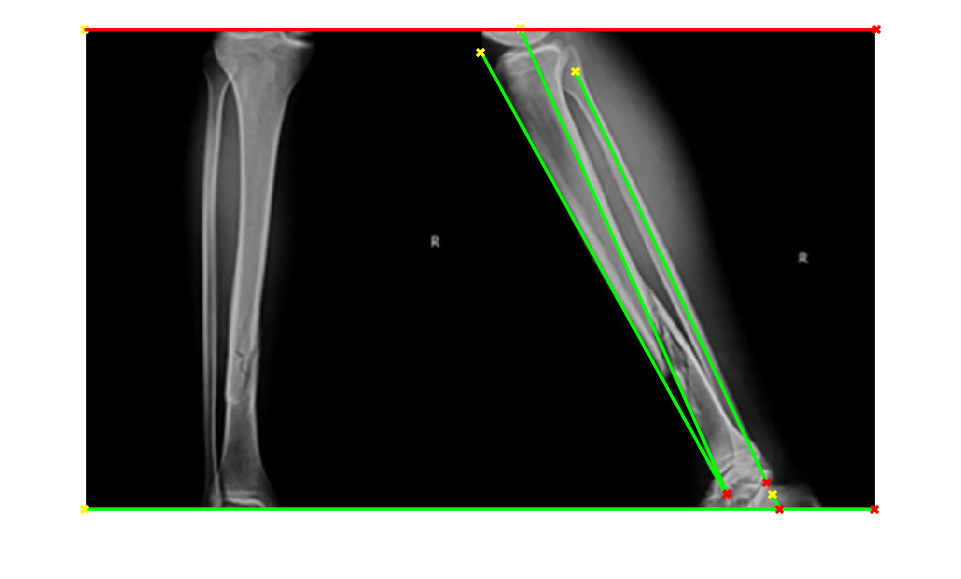

figure, imshow(I), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','red');

lines = struct2table(lines);


minDist = 10000;
prevMin = 10000;
p1 = 0;p2 = 0;
size = length(lines.point2);
for i = 1:size
    for j = 1:size
        if j == i
            continue;
        else
            dist = sqrt(sum((lines.point2(i)-lines.point2(j)).^2));
            minDist = min(dist,prevMin);
            if minDist ~= prevMin
                p1 = i;
                p2 = j;
            end
            prevMin = minDist;
        end 
    end
end

deviation = abs(lines.theta(p1) - lines.theta(p2))

deviation = 5